# Tuning ottimale controllori PID

## Schema di controllo

### Decentralizzato

Un controllore indipendente per ogni giunto. Le mutue influenze tra giunti sono viste come disturbi causati da un sistema sull'altro da compensare nel controllore dell'altro

## Struttura di controllo (per il singolo giunto)

### Doppio loop posizione-velocità (cascata) + SP weight

Ogni giunto è controllato da un controllore che riceve in input PV.POS e PV.VEL misurate e il set-point SP.POS. All'interno del controllore, alloggia il doppio loop, costituito, ad esempio, da:

- un *PD* per il **loop interno** (input: PV.VEL e MV del controllore esterno - output: coppia fornita al sistema)

- un *PID* per il **loop esterno** (input: PV.POS e SP.POS filtrato - output: velocità fornita in input al controllore interno)

- un *LPF* per implementare il **SP weight** (input: SP.POS - output SP.POS filtrato) 

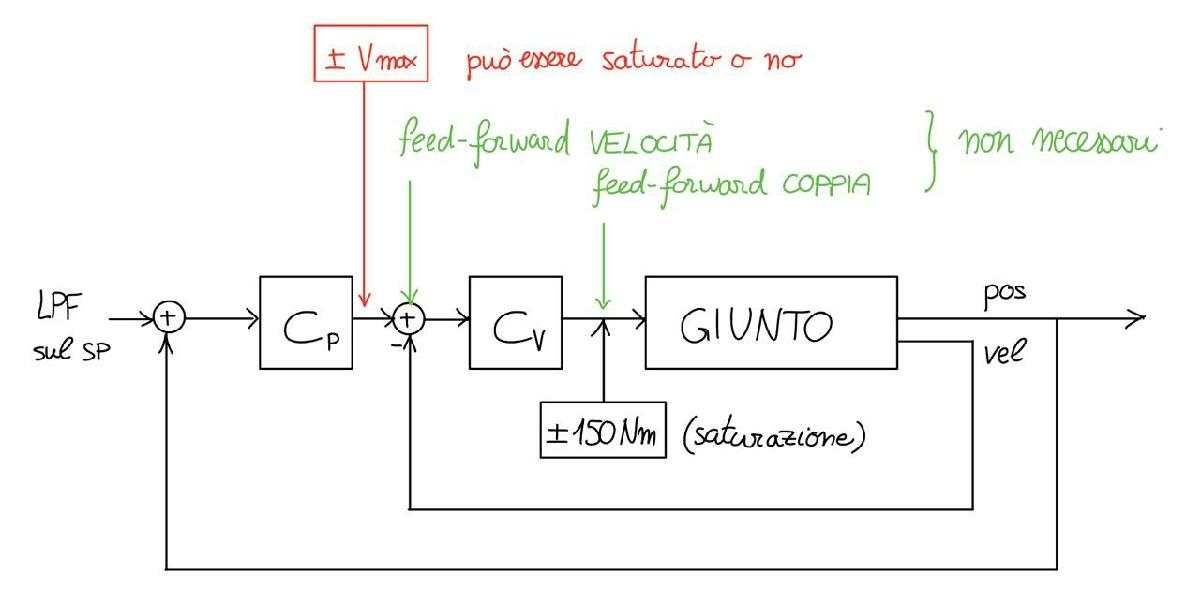

Note:

- implementare le **saturazioni** di coppia e velocità massima nei controllori opportuni

- implementare **anti-windup** per i controllori contenenti azione integrale

- valutare se possono servire i **feed-forward**

- loop interno veloce per la reiezione dei disturbi sul carico (influenze dell'altro giunto), loop esterno più lento ma sufficientemente veloce da seguire il SP in modo efficiente

- **taratura** di ogni sottocontrollore (`Cp_joint2`, `Cv_joint2`, `Cp_joint2`, `Cv_joint2`) in modo **ottimale** con `GlobalSearch`, includendo i **vincoli di robustezza e reiezione disturbi**

## Taratura ottima con vincoli robusti

Determinare $C(s)$ in modo che soddisfi vincoli in frequenza e ottimizzi una cifra di merito.

- PID con filtro sull'azione derivativa e filtro complessivo:    $C(s)=PID_{filt}(s)=\left(K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_{fd}s+1}\right) \cdot \frac{1}{T_{fu}s+1}$

- PID con filtro sull'azione derivativa:    $C(s)=PID(s)=K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_fs+1}$

- PD con filtro sull'azione derivativa:     $C(s)=PD(s)=K_p+\frac{K_d\cdot s}{T_fs+1}$

- PI:     $C(s)=PI(s)=K_p+\frac{K_i}{s}$

Eseguiamo il tuning nel dominio continuo (tariamo un controllore continuo sfruttando il modello continuo del processo) e in seguito discretizziamo il controllore ottenuto.

## Caricamento modelli dei processi

clear; close all; clc;

Aggiungo opzione per evitare la molteplicità di 360° nella base

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

## Giunto 2

### Caricare il modello

simulation.author = 'CL_M';
Nprova = 1;

modelName = strcat(simulation.author,'_model_', num2str(Nprova));
directoryModel = strcat('.\estimated_models\data\',modelName);
load(directoryModel);

### PD interno con filtro su tutta l'azione di controllo

Processo da controllare (da coppia motore a velocità)

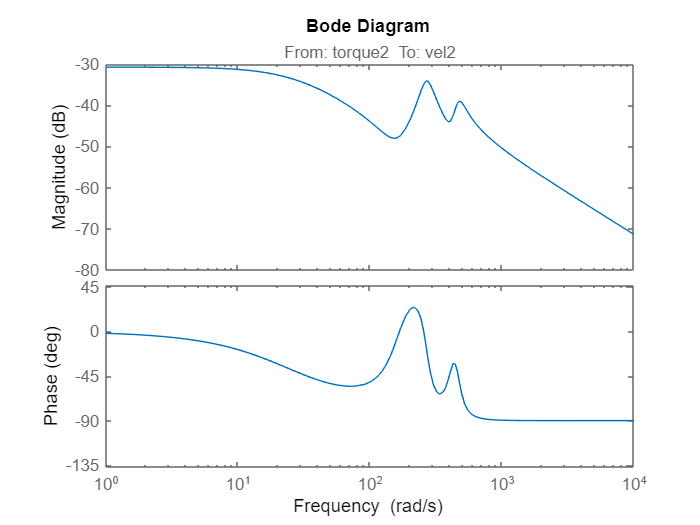

process = modelC_joint2;    % il modello deve essere nella forma dello spazio degli stati

bodeplot(process)

#### Cifra di merito da minimizzare


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

internal_joint2.wc_des = 10;
J = @(x)pid_filt_cost_function(x,process,internal_joint2.wc_des);

#### Vincoli

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Parametri da tarare

% Massima sensitività
internal_joint2.MS = 2;

% Reiezione disturbo di misura
internal_joint2.wh = 700;
internal_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint2.wl = 60;
internal_joint2.Dh_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint2.PM_min = 0;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

w_vector=logspace(log10(wpeso0),log10(wpeso1))';    % wpeso0 e wpeso1 vengono caricate all'atto del caricamento del modello stimato
w_vector=sort(unique([w_vector;internal_joint2.wl;internal_joint2.wh]));

nlcon = @(x)pid_filt_constraints(x, process, w_vector, ...
                                 internal_joint2.MS, internal_joint2.wh, internal_joint2.Fh_max, ...
                                 internal_joint2.wl, internal_joint2.Dh_max, internal_joint2.PM_min);

#### Ottimizzazione

Parametri da tarare

% Punto iniziale
internal_joint2.x0_Kp = 1000;
internal_joint2.x0_Ki = 0;
internal_joint2.x0_Kd = 0;
internal_joint2.x0_Tfd = 0;
internal_joint2.x0_Tfu = 0.02;

% Limiti inferiori
internal_joint2.lb_Kp = 100;
internal_joint2.lb_Ki = 0;
internal_joint2.lb_Kd = 0;
internal_joint2.lb_Tfd = 0;
internal_joint2.lb_Tfu = 0.001;

% Limiti superiori
internal_joint2.ub_Kp = 10000;
internal_joint2.ub_Ki = 0;
internal_joint2.ub_Kd = 0;
internal_joint2.ub_Tfd = 0;
internal_joint2.ub_Tfu = 1;

Lanciare ottimizzatore

parallel_flag = false;

if (parallel_flag)
    gs = MultiStart('Display','iter','MaxTime',60*5,'UseParallel',true); % GlobalSearch non supporta il calcolo parallelo
    addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
    n_startingPoints = 50;
    tic
    x = run(gs,problem,n_startingPoints)
    toc
else
    gs = GlobalSearch('Display','iter','MaxTime',60*5);
    x0 = [internal_joint2.x0_Kp, internal_joint2.x0_Ki, internal_joint2.x0_Kd, internal_joint2.x0_Tfd, internal_joint2.x0_Tfu];
    
    problem = createOptimProblem('fmincon','x0',x0, ...
                                 'objective',J, ...
                                 'lb',[internal_joint2.lb_Kp, internal_joint2.lb_Ki, internal_joint2.lb_Kd, internal_joint2.lb_Tfd, internal_joint2.lb_Tfu], ...
                                 'ub',[internal_joint2.ub_Kp, internal_joint2.ub_Ki, internal_joint2.ub_Kd, internal_joint2.ub_Tfd, internal_joint2.ub_Tfu], ...
                                 'nonlcon',nlcon);
    tic
    x = run(gs,problem)
    toc
end

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0      145      -278.1                                  -278.1            2    Initial Point
     200     1501      -278.1                                   -5156           -2    Stage 1 Local
     202     1644      -278.1         -2717       -278.1        -5156           -2    Stage 2 Local
     206     1798      -278.1         -2742        -2717        -5156           -2    Stage 2 Local
     222     1969      -278.1         -2925        -2742        -5156           -2    Stage 2 Local
     224     2126      -278.1         -2933        -2925        -5156           -2    Stage 2 Local
     226     2289      -278.1         -2945        -2933        -5156           -2    Stage 2 Local
     240     2481      -278.1         -3056        -2945        -5156           -2    Stage 2 Local


x = 	1.0e+03 *

    8.2140         0         0         0    0.0006


Elapsed time is 300.492093 seconds.


#### Controllore ottenuto

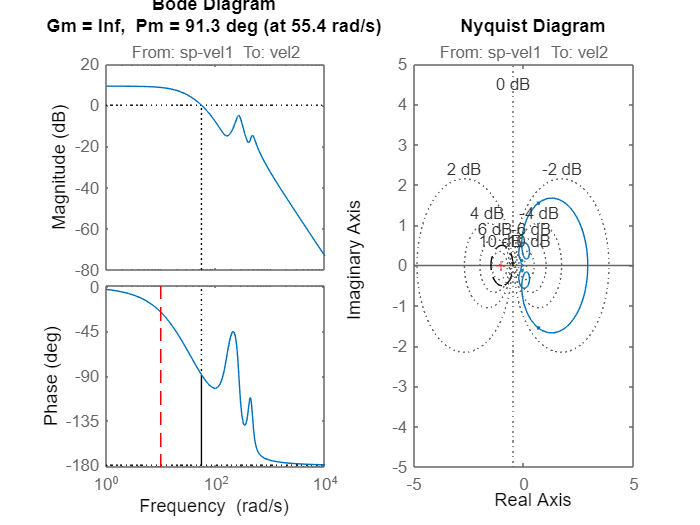

Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5);

s = tf('s'); % variabile s per il dominio delle frequenze

Tfu = 1/80; % manual tuning del filtro su tutta l'azione di controllo
Ki = 0;
Kd = 0;
Tfd = 0;
Kp = 100;


Cv_joint2 = (Kp+Ki/s+Kd*s/(Tfd*s+1)) * 1/(Tfu*s+1);   % progettiamo un controllore nella forma della funzione di trasferimento
Cv_joint2.InputName = 'sp-vel1';
Cv_joint2.OutputName = 'torque';

Loop_int_joint2 = process*Cv_joint2;



figure
subplot(1,2,1)
margin(Loop_int_joint2)
hold on
plot(internal_joint2.wc_des*[1 1],ylim,'--r')
hold off

subplot(1,2,2)
% MS = max(S) = max(1/(1+L)) -> 1/Ms = min(1+L) = min(L-(-1))
nyquist(Loop_int_joint2)
axis equal
grid on 
hold on
angolo=linspace(-pi,pi);
plot(-1+1/internal_joint2.MS*sin(angolo),1/internal_joint2.MS*cos(angolo),'--k')
hold off
xlim([-5 5]); ylim([-5 5])

### Salvataggio parametri tarati

PID_int_joint2_data.Kp = Kp;
PID_int_joint2_data.Ki = Ki;
PID_int_joint2_data.Kd = Kd;
PID_int_joint2_data.Tfd = Tfd;
PID_int_joint2_data.Tfu = Tfu;
    
paramsDirectory = '.\src\controllers\params\PID_int_joint2';    
save(paramsDirectory,'PID_int_joint2_data') 

### PID esterno con filtro su tutta l'azione di controllo

Processo da controllare (da velocità - set point per il controllore interno - a posizione)

process_ext = minreal(tf(Cv_joint2*modelC_joint2 * 1/(1+Cv_joint2*modelC_joint2)) * 1/s)

process_ext =
 
  From input to output "torque":
                                
  2.159e04 s^4 + 4.28e06 s^3    
                                
          + 4.467e09 s^2        
                                
          + 4.057e11 s          
                                
                      + 9.936e13
                                
  -------------------------------
                                 
  s^7 + 276.1 s^6 + 3.367e05 s^5 
                                 
          + 5.826e07 s^4         
                                 
          + 2.302e10 s^3         
                                 
          + 2.126e12 s^2         
                                 
                    + 1.337e14 s 
                                 
 
Continuous-time transfer function.



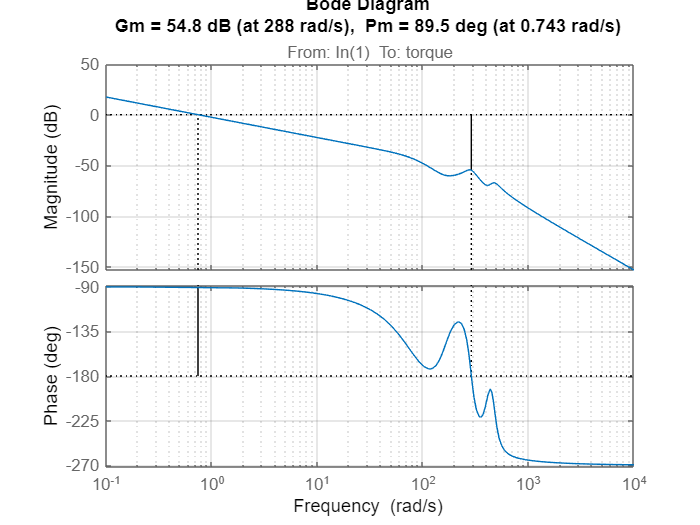

figure
margin(process_ext)
grid on

Necessario integratore perchè il modello in uscita fornisce la velocità, mentre noi vogliamo controllare la posizione.

**N.B.: il controllore esterno ****non**** vede **`Cv*P*1/s`**, ma **`Cv*P/(1+Cv*P)*1/s`** (in pratica vede tutto il sistema interno in closed-loop!**

#### Cifra di merito da minimizzare


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

external_joint2.wc_des = 50;
J = @(x)pid_filt_cost_function(x,process_ext,external_joint2.wc_des);
% J = @(x)pi_filt_cost_function(x,process_ext,external_joint2.wc_des);

#### Vincoli

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Parametri da tarare

% Massima sensitività
external_joint2.MS = 1.4;

% Reiezione disturbo di misura
external_joint2.wh = 700;
external_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint2.wl = 60;
external_joint2.Dh_max = 0.1;

% Minimo margine di fase tollerabile
external_joint2.PM_min = 60;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

w_vector=logspace(log10(wpeso0),log10(wpeso1))';    % wpeso0 e wpeso1 vengono caricate all'atto del caricamento del modello stimato
w_vector=sort([w_vector;external_joint2.wl;external_joint2.wh]);

nlcon = @(x)pid_filt_constraints(x, process_ext, w_vector, ...
                                 external_joint2.MS, external_joint2.wh, external_joint2.Fh_max, ...
                                 external_joint2.wl, external_joint2.Dh_max, external_joint2.PM_min);
% nlcon = @(x)pi_filt_constraints(x, process_ext, w_vector, ...
%                                  external_joint2.MS, external_joint2.wh, external_joint2.Fh_max, ...
%                                  external_joint2.wl, external_joint2.Dh_max, external_joint2.PM_min);

#### Ottimizzazione - esterno

Parametri da tarare

% Punto iniziale
external_joint2.x0_Kp = 150;
external_joint2.x0_Ki = 1;
external_joint2.x0_Kd = 0;
external_joint2.x0_Tfd = 0;
external_joint2.x0_Tfu = 0;

% Limiti inferiori
external_joint2.lb_Kp = 10;
external_joint2.lb_Ki = 10;
external_joint2.lb_Kd = 0;
external_joint2.lb_Tfd = 0;
external_joint2.lb_Tfu = 0;

% Limiti superiori
external_joint2.ub_Kp = 1000;
external_joint2.ub_Ki = 100;
external_joint2.ub_Kd = 0;
external_joint2.ub_Tfd = 0;
external_joint2.ub_Tfu = 0;

Lanciare ottimizzatore

parallel_flag = false;

x0 = [internal_joint2.x0_Kp, internal_joint2.x0_Ki, internal_joint2.x0_Kd, internal_joint2.x0_Tfd, internal_joint2.x0_Tfu];
% x0 = [internal_joint2.x0_Kp, internal_joint2.x0_Ki];
    
problem = createOptimProblem('fmincon','x0',x0, ...
                             'objective',J, ...
                             'lb',[external_joint2.lb_Kp, external_joint2.lb_Ki, external_joint2.lb_Kd, external_joint2.lb_Tfd, external_joint2.lb_Tfu], ...
                             'ub',[external_joint2.ub_Kp, external_joint2.ub_Ki, external_joint2.ub_Kd, external_joint2.ub_Tfd, external_joint2.ub_Tfu], ...
                             'nonlcon',nlcon);
%     problem = createOptimProblem('fmincon','x0',x0, ...
%                                  'objective',J, ...
%                                  'lb',[external_joint2.lb_Kp, external_joint2.lb_Ki], ...
%                                  'ub',[external_joint2.ub_Kp, external_joint2.ub_Ki], ...
%                                  'nonlcon',nlcon);

if (parallel_flag)
    gs = MultiStart('Display','iter','UseParallel',true); % GlobalSearch non supporta il calcolo parallelo
    addAttachedFiles(gcp,["pid_filt_constraints.m" "pid_filt_cost_function.m"]) % Usare se si abilita il pool parallelo su un Cluster online
    n_startingPoints = 50;
    tic
    x = run(gs,problem,n_startingPoints)
    toc
else
    gs = GlobalSearch('Display','iter','MaxTime',60*3);
    tic
    x = run(gs,problem)
    toc
end

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0       59      -367.7                                  -367.7           -2    Initial Point
     200     1602      -20.32                                  -20.32            2    Stage 1 Local
     205     1685      -20.32        -27.43       -20.32         -324           -2    Stage 2 Local
     206     1785      -20.32        -30.29       -27.43       -324.1           -2    Stage 2 Local
     207     1868      -20.32        -44.09       -30.29       -324.4           -2    Stage 2 Local
     208     1957      -20.32        -77.59       -44.09       -325.3           -2    Stage 2 Local
     209     2032      -20.32        -83.03       -77.59       -325.4           -2    Stage 2 Local
     210     2092      -20.32        -95.03       -83.03       -325.8           -2    Stage 2 Local


x =    19.7640   10.0035         0         0         0


Elapsed time is 180.441950 seconds.


#### Controllore ottenuto

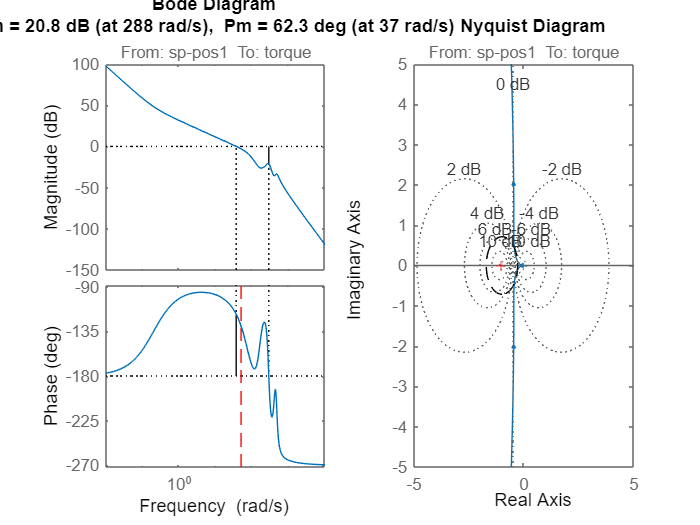

% Kp=x(1); Ki=x(2);
Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5);

% Adattamento manuale dei parametri
Kp=50;

Cp_joint2 = (Kp+Ki/s+Kd*s/(Tfd*s+1)) * 1/(Tfu*s+1);   % progettiamo un controllore nella forma della funzione di trasferimento
Cp_joint2.InputName = 'sp-pos1';
Cp_joint2.OutputName = 'vel';

Loop_ext_joint2 = process_ext*Cp_joint2;

figure
subplot(1,2,1)
margin(Loop_ext_joint2)
hold on
plot(external_joint2.wc_des*[1 1],ylim,'--r')
hold off

subplot(1,2,2)
% MS = max(S) = max(1/(1+L)) -> 1/Ms = min(1+L) = min(L-(-1))
nyquist(Loop_ext_joint2)
axis equal
grid on 
hold on
angolo=linspace(-pi,pi);
plot(-1+1/external_joint2.MS*sin(angolo),1/external_joint2.MS*cos(angolo),'--k')
hold off
xlim([-5 5]); ylim([-5 5])

### Salvataggio parametri tarati

PID_ext_joint2_data.Kp = Kp;
PID_ext_joint2_data.Ki = Ki;
PID_ext_joint2_data.Kd = Kd;
PID_ext_joint2_data.Tfd = Tfd;
PID_ext_joint2_data.Tfu = Tfu;
    
paramsDirectory = '.\src\controllers\params\PID_ext_joint2';    
save(paramsDirectory,'PID_ext_joint2_data') 